# Loading the Classifier

The classifier consists of an *ensemble* of a large number of binary decision trees. Each tree aims to classify a cell into a randomly-selected group of cell types, and the resulting scores are combined across trees to hone in on the single cell type that is most compatible with the preferred group.

The parameters for the model are tuned by Bayesian Optimization and are stored in a text file:

params = readparamsfile('5407/5407params.in');
disp(params);

              nFeatures: 91
                 nFolds: 3
                nLambda: 36
                  alpha: 0.8498
               nRepeats: 17
               maxDepth: 5
                minSize: 34
               maxTrees: 90
               minTrees: 70
              stopCount: 21
          stopThreshold: 0.3262
           ensembleSize: 51
    negativeProbability: 0.4295
    positiveProbability: 0.2659
                nLabels: 31
                   ECOC: [31×51 double]



The classifier is trained in C++ according to the parameters and output is stored in a directory:

ensemble1 = PsthEnsemble('5407/fold1', params.ECOC);
disp(ensemble1);

  PsthEnsemble with properties:

          forests: [1×51 PsthForest]
             ecoc: [31×51 double]
         lastPsth: []
    lastCellCount: []
             size: 29029312



Information about the training performance is stored at each node along with the weights:

disp(ensemble1.forests(1).trees(1).left)

  PsthNode with properties:

                       N: 298
               timeIndex: [12×1 double]
        timeIndexQuality: [12×1 double]
           spotSizeIndex: [12×1 double]
    spotSizeIndexQuality: [12×1 double]
            indexQuality: [12×1 double]
                   beta0: 0.4683
                   beta1: [12×1 double]
                      mu: [12×1 double]
                    istd: [12×1 double]
                  lambda: 2.9222e-04
                deviance: 0.9990
             uncertainty: 0.4249
                 support: 0.0096
                    left: [1×1 PsthLeaf]
                   right: [1×1 PsthNode]



# Loading Cell Data

Although the classifier is trained to be as agnostic as possible to the actual stimulus parameters, care must be taken to ensure the data is formatted properly. In particular, the input PSTH data should be a firing rate matrix of size `(351-by-1601-by-nCells)`, where the first dimension corresponds to times `[-1.0s, +2.5s]` relative to the onset of a 1s light step, and the second dimension corresponds to spot sizes `[0um, 1600um]`, imputed with the nearest-neighbor. The provided `rebinData` function can assist with proper formatting:

load("testing_unbinned.mat");
disp(testing);

  417×1 struct array with fields:

    cellName
    dataSet
    cellType
    SMS_PSTH
    PSTH_X
    SpotSizeVec



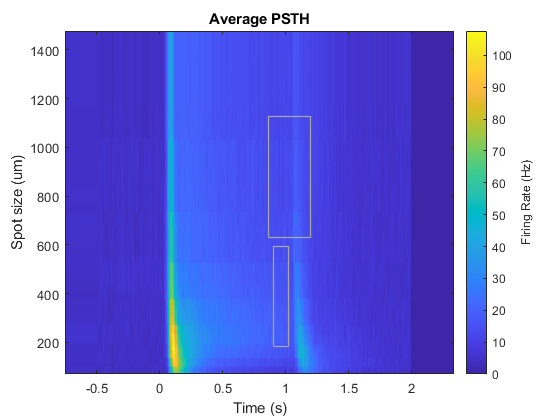

[tq,sq] = meshgrid(-1:.01:2.5,0:1600);
measured_times = {testing(:).PSTH_X};
minT = cellfun(@min,measured_times);
maxT = cellfun(@max,measured_times);
testing_rebinned = permute(reshape(...
    rebinData(...
        {testing(:).SMS_PSTH},...
        {testing(:).SpotSizeVec},...
        sq(:)',...
        [minT' maxT'],...
        tq(:),...
        .01...
    )...
    , [], 1601, 351),[3,2,1]);
imagesc(-1:.01:2.5,0:1600, mean(testing_rebinned,3)');
axis xy; xlabel('Time (s)'); ylabel('Spot size (um)'); h = colorbar; ylabel(h, 'Firing Rate (Hz)');
title('Average PSTH (all RGCs)');

`savePSTHtoBin` and `readPSTHfromBin` are provided as convenience functions for translating data to the formats expected by the C++ implementation.

# Classification

With a loaded `PsthEnsemble` and a PSTH, we can classify our cells:

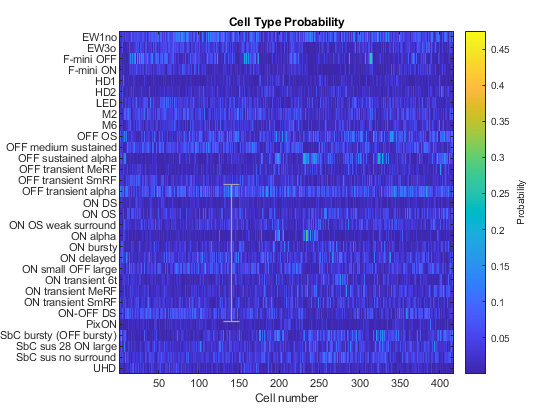

probabilities = ensemble1.classify(testing_rebinned, 2);
[trueLabelNames,~,trueLabels] = unique({testing(:).cellType}'); %by convention
imagesc(probabilities');
xlabel('Cell number'); yticks(1:31); yticklabels(trueLabelNames); h=colorbar; ylabel(h, 'Probability');set(gca,'fontSize',8);
title('Cell Type Probability');

One way to assess the classification performance is by the confusion matrix:

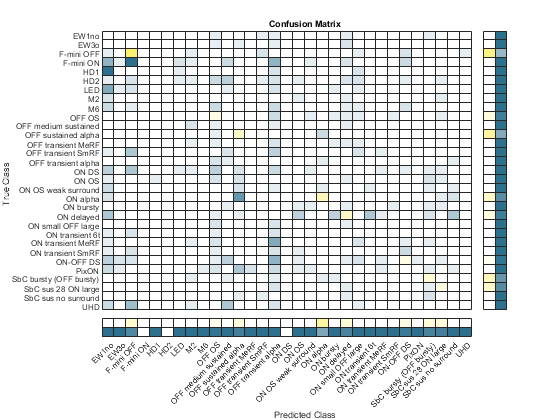

[~,bestMatch] = max(probabilities,[],2);
cm = confusionchart(trueLabelNames(trueLabels), trueLabelNames(bestMatch),...
    'RowSummary','row-normalized','ColumnSummary','column-normalized',...
    'fontSize',6);cm.DiagonalColor = '#FDE725';cm.OffDiagonalColor = '#2D708E';cm.Title = 'Confusion Matrix';